## Open or consolidate data files

clear
is_Mac = 0;
consolidate = 1;

if is_Mac
    save_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/general';
    data_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/single';
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw')) %addpath(genpath('.\sw'))
else
    save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\general';
    data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\single';
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
%database_header = ["ID","Item","Windspeed[m/s]","Airspeed[m/s]","Skew[deg]","Skew_sp[deg]","Mot_Status","Excitation","Mx[Nm]","My[Nm]","Mz[Nm]","Fx[N]","Fy[N]","Fz[N]","Mot_F[pwm]","Mot_R[pwm]","Mot_B[pwm]","Mot_L[pwm]","Ail_L[pwm]","Ail_R[pwm]","Elev[pwm]","Rud[pwm]","Pitch[deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_1.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;

if is_Mac
    path = '/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/OJF/calibration';
else
    path = 'C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\OJF\calibration';
end
name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = data.Fx(i)-int_cal(1);
    data.Fy(i) = data.Fy(i)-int_cal(2);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = data.Mx(i)-int_cal(4);
    data.My(i) = data.My(i)-int_cal(5);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.04].'; %[0,0,-1]90.5+5.5+8
%pole = [0,0,0].'; 
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,2);
data.Mz = m_e(:,3);

## **Question to be answered**

*How can the effectiveness of the ailerons be modelled with skew, airspeed, mot cmd(check if can assume no).*

How can the effectiveness of the tail be modelled with skew(check if can assume no), airspeed, mot cmd(check if can assume no), push cmd(check if can assume no). 

How can lift be modelled with respect to airspeed, skew, pitch and mot cmd(check if can assume no). 

Yawing moment and Roll moment from rotating the wing

**LEFT AILERON - Idle motors - Roll Moment**

The inital model has the form of:


$$b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3$$


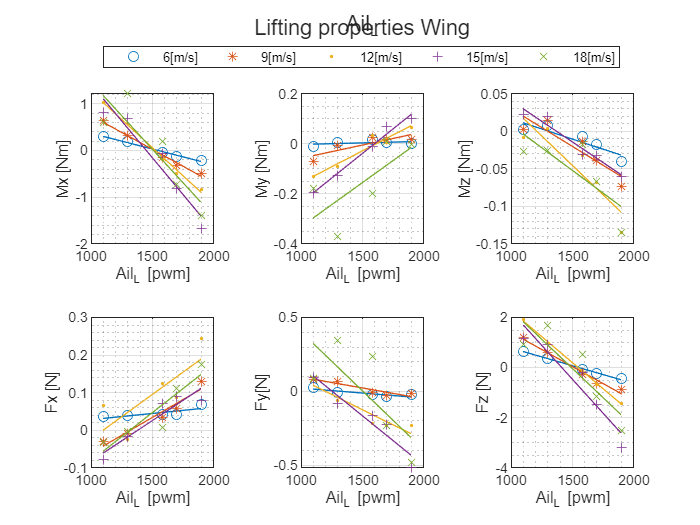

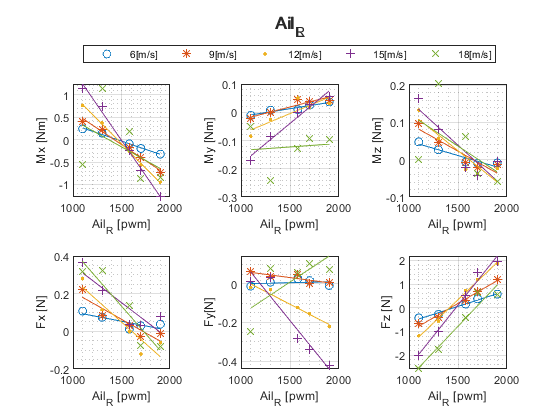

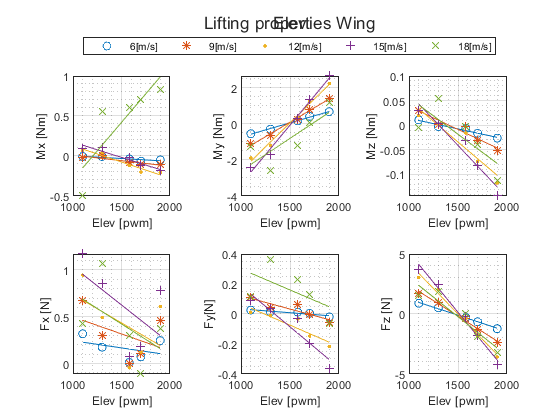

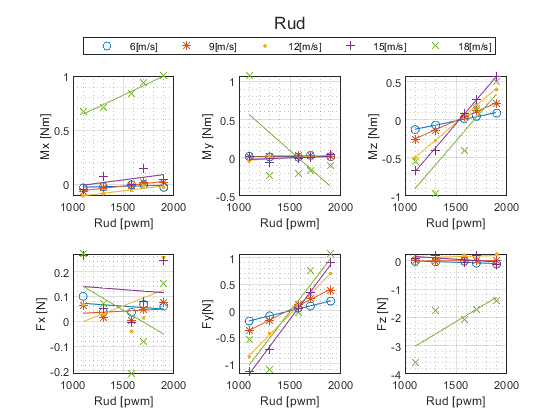

v = unique(data.Windspeed);
unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
leg_v = [];
for i=1:max(size(v))
    leg_v= [leg_v,strcat(string(round(v(i))),'[m/s]'),''];
end
for k=0:3
    figure(k+1)
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(data,[-1,k,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(data,[-1,5,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(19+k),out.(j)-bias.(j),1,i)
        end
        xlabel(unit_header(19+k))
        ylabel(unit_header(j))
        
        grid on
        grid minor

    end
    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

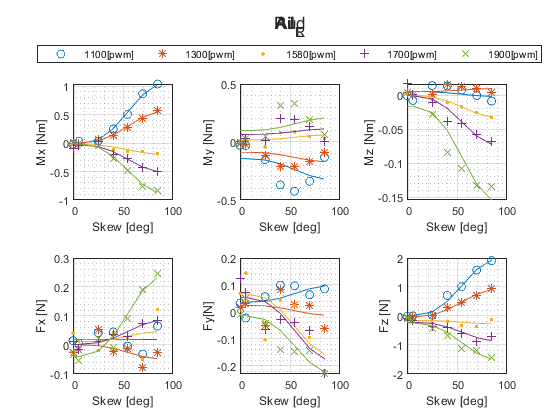

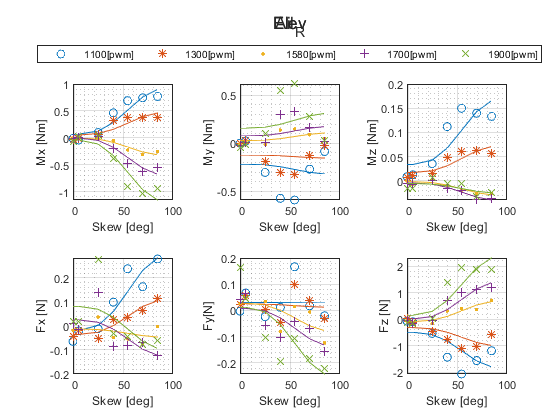

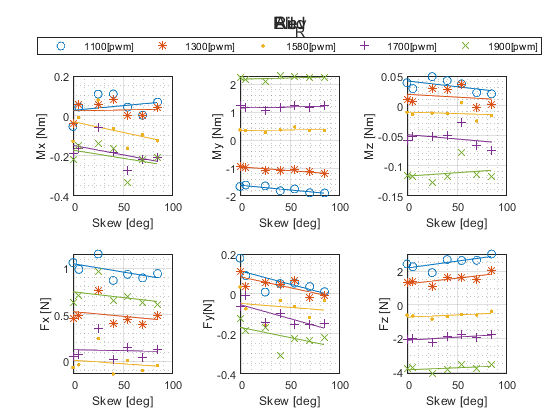

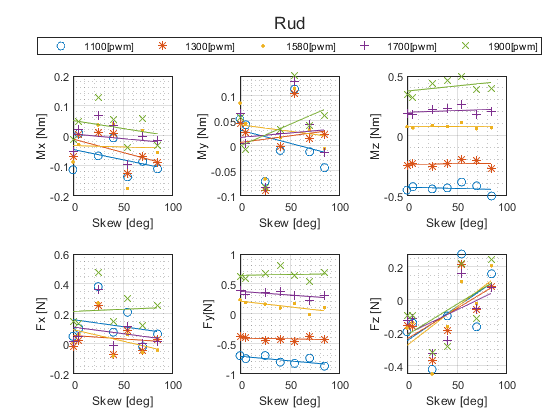

baseline = k;
cmd_idx = unique(data.Excitation);
cmd = [1100,1300,1580,1700,1900];
leg_cmd = [];
for i=1:max(size(cmd))
    leg_cmd= [leg_cmd,strcat(string(round(cmd(i))),'[pwm]'),''];
end
for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    if k < 2
        order = 12;
    else
        order=1;
    end
    for j=9:14
        nexttile
        for i=1:max(size(cmd_idx))
            out  = table_sifter(data,[-1,k,v(3),-1,-1,-1,0,cmd_idx(i),-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(data,[-1,5,v(3),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j)-bias.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        hold off

    end
    lgd = legend(leg_cmd,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

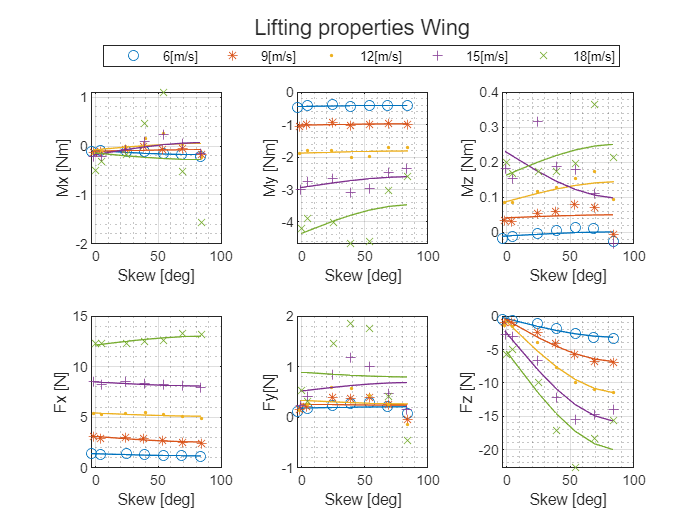

baseline = k;
%for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    order=10;
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(data,[-1,5,v(i),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        hold off

    end
    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,'Lifting properties Wing')

%end
% L = 0.5 rho Cl S v^2 sin^2
L = 0.5 * 1.225 * 1.56 * 0.235 ;


baseline = k;
figure(baseline+k+1)
clf
cla
t = tiledlayout(2,3);
order=10;
rmse_log = {};
coeffs = {};
for j=9:14
    nexttile
    prefilter = data(data.Windspeed<14,:);
    %prefilter = data;
    out  = table_sifter(prefilter,[-1,5,-1,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
    %p = [sin(deg2rad(x)).^(order-9),ones(size(x))]\y;
    %plot_special(out.(5),out.(j),order,i)
    %scatter3(out.(5),out.(3),out.(j),'*')
    [rmse_log_i,coeffs_i] = plot3_special(out.(5),out.(3),out.(j),1,5);
    rmse_log{j-8} = rmse_log_i;
    coeffs{j-8}   = coeffs_i;
    xlabel(unit_header(5))
    ylabel(unit_header(3))
    zlabel(unit_header(j))    
    grid on
    grid minor
    hold off
end

lsqr converged at iteration 3 to a solution with relative residual 0.73.
lsqr stopped at iteration 5 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 5) has relative residual 0.54.
lsqr converged at iteration 5 to a solution with relative residual 0.56.
lsqr converged at iteration 7 to a solution with relative residual 0.63.
lsqr converged at iteration 4 to a solution with relative residual 0.81.
lsqr converged at iteration 3 to a solution with relative residual 0.067.
lsqr stopped at iteration 5 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 5) has relative residual 0.053.
lsqr converged at iteration 7 to a solution with relative residual 0.051.
lsqr converged at iteration 7 to a solution with relative residual 0.054.
lsqr converged at iteration 5 to a solution with relative residual 0.24.
lsqr converged at iteration 

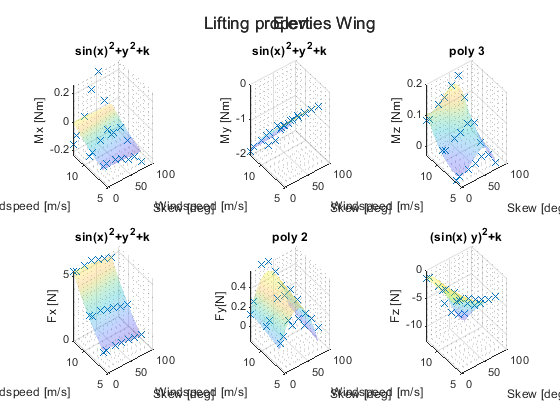

%lgd = legend(leg_v,'NumColumns',5);
%lgd.Layout.Tile = 'north';
title(t,'Lifting properties Wing')